# Using EstimateHRF_inAtlas

Estimate HRF in a convenient matlab structure for individual scan runs and group-level analysis. The below takes you through the process step-by-step.

by Michael Sun, Ph.D.

## Step 1a: Housekeeping: File Locations

`_________________________________________________________________________`

First we need to locate our fmri 4D files from our study

% Navigate to the correct directory
if ismac()      % I usually have the cluster smb mounted on a Mac like this
    root = '/Volumes/CANlab';
    cd('/Volumes/WASABI/derivatives/fmriprep')
elseif ispc()   % Otherwise on a PC or Linux box, it looks something like this
    % root = 'H:\Dropbox (Dartmouth College)\Tor Pinel datasets\Pinel_localizer\results\Brainomics_contrast_objects'
    root = '\\dartfs-hpc\rc\lab\C\CANlab\';
    cd('\\dartfs-hpc\rc\lab\C\CANlab\labdata\data\WASABI\derivatives\fmriprep')
else
    root = '/dartfs-hpc/rc/lab/C/CANlab/';
    cd('/dartfs-hpc/rc/lab/C/CANlab/labdata/data/WASABI/derivatives/fmriprep')
end
fmriprep_dir=pwd

fmriprep_dir = '\\dartfs-hpc\rc\lab\C\CANlab\labdata\data\WASABI\derivatives\fmriprep'

## Step 1b: Housekeeping: Checking Dependencies

`_________________________________________________________________________`

Then we need to check if the Matlab **Signal Processing Toolbox, SPM, **and the **CANLab Core Tools **are installed. If not, use addpath() to add them to your Matlab path e.g., **addpath(genpath(YOUR_PATH_TO_CANLAB_CORE));**

% Check if Signal Processing Toolbox is installed
if license('test', 'Signal_Toolbox')
    fprintf('Signal Processing Toolbox is installed.\n');
else
    fprintf('Signal Processing Toolbox is not installed.\n');
end

Signal Processing Toolbox is installed.



% Optionally, you can also get the version information if it's installed
toolboxInfo = ver;
toolboxNames = {toolboxInfo.Name};
if any(strcmp(toolboxNames, 'Signal Processing Toolbox'))
    idx = find(strcmp(toolboxNames, 'Signal Processing Toolbox'));
    toolboxVersion = toolboxInfo(idx).Version;
    fprintf('Signal Processing Toolbox version: %s\n', toolboxVersion);
end

Signal Processing Toolbox version: 9.2



% Check if SPM is installed
if exist('spm', 'file') == 2
    fprintf('SPM is installed.\n');
else
    fprintf('SPM is not installed.\n');
end

SPM is installed.



% Check if CanlabCore Tools are installed
toolboxName = 'CANLab Core'; % Replace with the actual toolbox name
functionName = 'fmri_data'; % Replace with a function or file name from the toolbox

% Check if the function or file associated with the toolbox exists
if exist(functionName, 'file') == 2
    fprintf('%s is installed.\n', toolboxName);
else
    fprintf('%s is not installed.\n', toolboxName);
end

CANLab Core is installed.


You should have these in your path, otherwise you'll run into trouble down the line:

- SPM12

- CanlabCore Object-Oriented Tools

- Canlab Second_level_analysis_template_scripts

- Canlab Masks_Private

- Neuroimaging_Pattern_Masks

% If CANLab Core is installed correctly, you should be able to run this
% line:
subjects=canlab_list_subjects(fmriprep_dir, 'sub-*');
condition_names={'hot','warm','imagine'};

## Step 2: Pick your raw 4D fMRI file, and their associated onsets and durations

`_________________________________________________________________________`

- Best use a 4D file that's minimally preprocessed like an fmriprep ***desc-preproc_bold.nii** file

- If you used SPM-style CANlab first-level modelling, its as easy as grabbing the relevant .mat files for the scan.

% Gather all the relevant files
file=dir(fullfile(fmriprep_dir, subjects{1}, 'ses-*', 'func','*bodymap*MNI152NLin2009cAsym*preproc_bold.nii.gz'));

filenum =      2

a=fullfile({file.folder}',{file.name}');


Using default mask: C:\Users\Admin\Documents\GitHub\canlab\CanlabCore\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 463243680 bytes
Loading image number:  1160
Elapsed time is 637.815828 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
.fullpath should have image name for each image column in .dat
Attempting to expand image filenames in case image list is unexpanded 4-D images
Number of unique values in dataset: 42052  Bit rate: 15.36 bits


% Select one file for processing

sub = 1×1 cell array
    {'sub-SID000002'}

filenum=2;

ses = 1×1 cell array
    {'ses-03'}

fname=a{filenum};

run = 1×1 cell array
    {'run-02'}

f=fmri_data(fname);
sub=strcat('sub-',extractBetween(fname, 'sub-', filesep));
ses=strcat('ses-',extractBetween(fname, 'ses-', filesep));
run=strcat('run-',extractBetween(fname, 'run-', '_'));

% Gather all relevant first-level files to get onset and duration times.
firstlvl_path=fileparts(strrep(fname, 'fmriprep', ['fmriprep-try2', filesep, 'CANLab_firstlvl']));
firstlvl_path=strrep(firstlvl_path, 'func', '');

run_without_zeros = strrep(run, 'run-0', 'run-');
% Initialize run_values with both variants
run_values = {run{1}, run_without_zeros{1}};

% Initialize a flag to indicate if the directory was found
directory_found = false;

% Loop through the run values
for i = 1:numel(run_values)
    % Replace 'func' with the current run value
    current_run = run_values{i};
    current_firstlvl_path = fullfile(firstlvl_path, current_run);
    
    % Use dir to list directories matching the pattern
    firstlvl_dir = dir(fullfile(current_firstlvl_path, '*firstlvl'));
    
    % Check if the directory exists
    if ~isempty(firstlvl_dir)
        % Directory found, set the flag and break out of the loop
        directory_found = true;
        break;
    end
end

% Use the directory found, if any
if directory_found
    % Process the found directory here
    disp(['Directory found for ' current_run]);
    firstlvl_dir = dir(fullfile(current_firstlvl_path, '*firstlvl'));
else

Directory found for run-2


    % Handle the case when neither directory was found
    disp('No directory found for either run-0X or run-X');
end

firstlvl_files=dir(fullfile(firstlvl_dir.folder, firstlvl_dir.name));

% firstlvl_hot;
% Get Onset and Duration
for c = 1:numel(condition_names)
    full_path_pattern = fullfile(firstlvl_dir.folder, firstlvl_dir.name, [condition_names{c},'*.mat']);
    c_files=dir(full_path_pattern);
    ons_dur(c)=load(fullfile(c_files.folder, c_files.name));
    
    ons(c)=ons_dur(c).onset;
    dur(c)=ons_dur(c).duration;
end

## Step 2: Set your parameters for preprocessing and HRF fitting

`_________________________________________________________________________`

EstimateHRF_inAtlas takes 5 arguments: **fmri_data**, **PREPROC_PARAMS**, **HRF_PARAMS**, **atlas**, **ROIs**, and **outfile** filename.

- fmri_data object of your 4D fmri file

- **PREPROC_PARAMS** structure: stores all parameters for preprocessing your 4D file.

- **HRF_PARAMS** structure: stores all parameters for HRF estimation. Condition is a vertical vector of onsets that is fed into **hrf_fit_one_voxel()** you want to model. We can use the helper function **generateConditionTS()** to create this for us. 

Condition=generateConditionTS(f, condition_names, ons, dur);

Next, we'll fill in everything else:

PREPROC_PARAMS.TR=0.46;   % TR in seconds
PREPROC_PARAMS.smooth=6;  % 6mm FWHM smoothing kernel

HRF_PARAMS.Condition=Condition;
HRF_PARAMS.CondNames=condition_names;
HRF_PARAMS.TR=0.46;     % TR in seconds
HRF_PARAMS.T=22;        % Time Window that you want estimated in seconds
HRF_PARAMS.FWHM=6;      % 6mm FWHM smoothing kernel
HRF_PARAMS.alpha=0.001; % alpha level
HRF_PARAMS.types={'FIR','CHRF'}; % Choices are 'FIR', 'IL', and 'CHRF', but 'IL' often gets stuck so I don't include it here.

## Step 3: Set your Atlas and ROIs

`_________________________________________________________________________`

Pick the masks that you want to estimate HRFs for using:

- an **atlas** object

- a cell array of cellstrings with labels matching atlas**.labels** field

at=load_atlas('canlab2018_2mm'); % In this example we use the CANlab 2018 2mm atlas

Loading atlas: CANlab_combined_atlas_object_2018_2mm.mat


% rois={'Ctx_4_L', 'Ctx_4_Ra_1', 'Ctx_V1_L', 'Ctx_V1_R'}; % Picked an arbitrary 4 labels in the atlas
rois=at.labels; % Or you can do this. Warning: This runs all regions in the atlas.

## Step 4: Set your output filepath

`_________________________________________________________________________`

Pick a cellstring that reflects the filepath and filename you want to save your results for. Leave off the file extension, as EstHRF_inAtlas will save out a filename with the **.mat** extension.

outfile=strrep(fname, '_bold.nii.gz', '_bold-HRF');
outfile=strrep(outfile, 'fmriprep', 'estHRF');
outfile=strrep(outfile, ['func', filesep], '')

outfile = '\\dartfs-hpc\rc\lab\C\CANlab\labdata\data\WASABI\derivatives\estHRF\sub-SID000002\ses-03\sub-SID000002_ses-03_task-bodymapST2_acq-mb8_run-02_space-MNI152NLin2009cAsym_desc-preproc_bold-HRF'

## Step 5: Run the code

`_________________________________________________________________________`

Now run the code. You will get: 

- **timecourse:** A cell-array of timecourse vectors for every estimated HRF fit-type x region.

- **HRF:** An HRF structure object with descriptive information and summary statistics to be passed on to second-level analysis

- Nifti objects will be written out in your current working directory for the timeseries of each fit-type x voxel x condition so that you can re-mask them for new regions, saving you time.

% Run your time-series analysis on your 4-D fmri file. Note: Requires the Matlab Signal Processing Toolbox
tic
[timecourse, HRF]=EstimateHRF_inAtlas(f, PREPROC_PARAMS, HRF_PARAMS, at, rois, outfile);

1160Smoothed images with   6 FWHM filter
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.
HRF estimation
HRF estimation
matrix_eval_function.m
_______________________________
Evaluating this function on 99837 variables:
    @(tc)hrf_fit_one_voxel_meval(tc,TR,Runc,T,method,mode)
...using this command:
[varargout{1}(i,:),varargout{2}(i,:),varargout{3}(i,:),varargout{4}(i,:),varargout{5}(i,:),varargout{6}(i,:)] = fhandle(double(Y(:,i)));
_______________________________
matrix_eval_function.m
_______________________________
Evaluating this function on 99837 variables:
    @(tc)hrf_fit_one_voxel_meval(tc,TR,Runc,T,method,mode)
...using this command:
[varargout{1}(i,:),varargout{2}(i,:),varargout{3}(i,:),varargout{4}(i,:),varargout{5}(i,:),varargout{6}(i,:)] = fhandle(double(Y(:,i)));
_______________________________
Running ... Done 100%
_______________________________

Done in   0 hrs,  14 min, with 0.009 s per variable 
Writing: 

toc

Elapsed time is 2149.148665 seconds.


## Step 6: Describe and/or Visualize Results

`_________________________________________________________________________`

You can now generate summary text from your HRF structure object.

describeHRF(HRF);

The FIR fitted Ctx_V1_L features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  27 features 1 peak(s), (at TR(s) 8 and features an AUC of 152.8803 (voxel-normed: 0.07796).
The FIR fitted Ctx_V1_R features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  28 features 1 peak(s), (at TR(s) 8 and features an AUC of 233.0418 (voxel-normed: 0.11401).
The FIR fitted Ctx_MST_L features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  46 features 2 peak(s), (at TR(s) 9  24 and features an AUC of 242.6137 (voxel-normed: 2.3555).
The FIR fitted Ctx_MST_R features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  28 features 1 peak(s), (at TR(s) 8 and features an AUC of 91.8021 (voxel-normed: 0.95627).
The FIR fitted Ctx_V6_L features 1 phases of activity for the hot condition
Phase 1, spanning TRs 1  18 features 1 peak(s), (at TR(s) 3 and features an AUC of 87.5431 (voxel-normed: 0.3149).
The FIR fitted Ctx_V6_R features 

You can also generate a table of summary statistics from your HRF structure object.

T=generateHRFTable(HRF);

      Type              Region              Condition     PhaseNum    PhaseSpan    Peaks    Troughs      TimeToPeak              AUC               AUC_VoxNormed    
    ________    _______________________    ___________    ________    _________    _____    _______    _______________    __________________    ____________________
    {'FIR' }    {'Ctx_V1_L'           }    {'hot'    }       0         0     0       0         0       {[          0]}                     0                       0
    {'CHRF'}    {'Ctx_V1_L'           }    {'hot'    }       1         1    29       1         0       {[          7]}      181.182885537839      0.0923931083823759


Finally, you can generate plots for any region label in your atlas

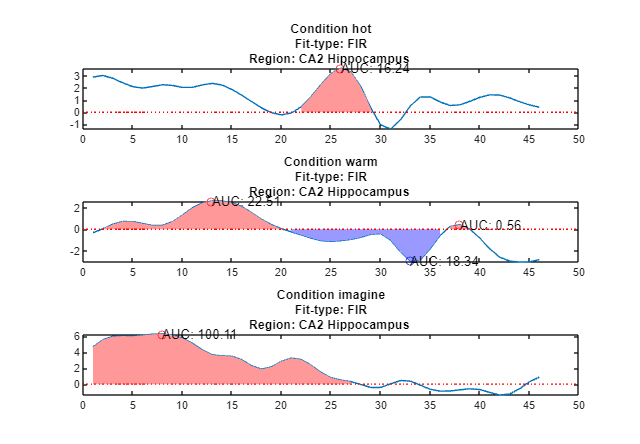

plotHRF(avgHRF, 'FIR', 'CA2_Hippocampus_') % Picked a random ROI to plot

## Step 7: Run for your Entire Study

`_________________________________________________________________________`

To run EstimateHRF_inAtlas for an entire study, you will need to merge a table of all of your 4D files with the onset and duration information that is found in your first-level directories. Here's how I might do it:

### a. First generate a 4-D infoTable

% Define the file pattern to match preprocessed bold files
filePattern = fullfile(fmriprep_dir, 'sub-*', 'ses-*', 'func', '*MNI152NLin2009cAsym*preproc_bold.nii.gz');

% List all matching files
preprocFiles = dir(filePattern);

% Initialize empty arrays to store subject, session, and run information
subjects = {};
sessions = {};
runs = {};
scanfile = {};

% Loop through the preprocessed bold files
for i = 1:length(preprocFiles)
    % Parse subject, session, and run information from the file path
    filePath = fullfile(preprocFiles(i).folder, preprocFiles(i).name);
    parts = strsplit(filePath, filesep);
    
    % Initialize subject, session, and run variables
    subject = '';
    session = '';
    run = '';
    
    % Find the cells that contain 'sub', 'ses', and 'func'
    subIdx = find(contains(parts, 'sub'));
    sesIdx = find(contains(parts, 'ses'));
    runIdx = find(contains(parts, 'run'));
    
    % Extract subject, session, and run labels if found
    if any(~isempty(subIdx) & subIdx <= numel(parts))
        subject = parts{subIdx};
    end
    if any(~isempty(sesIdx) & sesIdx <= numel(parts))
        session = parts{sesIdx};
    end
    if any(~isempty(runIdx) & runIdx <= numel(parts))
        run = char(strcat('run-', extractBetween(parts{runIdx}, 'run-', '_')));
    end
    
    % Append information to arrays
    subjects{end+1} = subject;
    sessions{end+1} = session;
    runs{end+1} = run;
    scanfile{end+1} = parts{end};
end

% Create a table with the extracted information
infoTable = table(subjects', sessions', runs', scanfile', 'VariableNames', {'Subject', 'Session', 'Run', 'ScanFile'});

% Display the table
disp(infoTable);

% -----------------------------------------------------------------------------------------------------------------------

### b. Generate a table column of onsets and durations

% Gather all relevant first-level files to get onset and duration times.
firstlvl_path=fullfile(fmriprep_dir, 'CANLab_firstlvl');
tic
dict={};
for r =1:height(infoTable)
    run_without_zeros = strrep(char(infoTable{r, "Run"}), 'run-0', 'run-');
    % Initialize run_values with both variants
    run_values = {char(infoTable{r, "Run"}), run_without_zeros};
    % Initialize a flag to indicate if the directory was found
    directory_found = false;

    % Loop through the run values
    for i = 1:numel(run_values)
        current_run = run_values{i};
        current_firstlvl_path = fullfile(firstlvl_path, char(infoTable{r, "Subject"}), char(infoTable{r, "Session"}), current_run);
        
        % Use dir to list directories matching the pattern
        firstlvl_dir = dir(fullfile(current_firstlvl_path, '*firstlvl'));
        
        % Check if the directory exists
        if ~isempty(firstlvl_dir)
            % Directory found, set the flag and break out of the loop
            directory_found = true;
            break;
        end
    end

    % mats=dir(fullfile(firstlvl_path, char(infoTable{r, "Subject"}), char(infoTable{r, "Session"}), char(infoTable{r, "Run"}), '*_firstlvl', '*.mat'))
    mats=dir(fullfile(firstlvl_dir.folder, firstlvl_dir.name, '*.mat'));
    % For each .mat, strip the name of .mat and generate a column if it doesn't exist 
    for i = 1:length(mats)
        % Extract the filename without the .mat extension
        filename = mats(i).name;
        [~, name, ~] = fileparts(filename);
        
        % Step 3: Check if the column exists in infoTable
        if ~ismember(name, infoTable.Properties.VariableNames)
            % Step 4: If the column doesn't exist, add it with empty values
            % Create an empty cell for each row in the new column
            infoTable.(name) = cell(size(infoTable, 1), 1);
        end
        
        data=load(fullfile(mats(i).folder, mats(i).name));
        % Check if 'onset' and 'duration' exist, and if not, check for 'R'
        if isfield(data, 'onset') && isfield(data, 'duration')
            onset = data.onset;
            duration = data.duration;
            % Create a dictionary to hold 'onset' and 'duration'
            infoTable.(name){r} = containers.Map({'onset', 'duration'}, {onset, duration});
        elseif isfield(data, 'R')
            % If 'onset' and 'duration' don't exist, but 'R' does, use 'R'
            R = data.R;
            infoTable.(name){r} = R;
        else
            % Handle the case where neither 'onset' and 'duration' nor 'R' exist
            onset = [];
            duration = [];
            R=[];
            infoTable.(name){r}=[];
        end
        
    end
end
toc

% ---------------------------------------------------------------------------------------

### c. Now merge the two to create a JOB table and save it somewhere:

tic
% Assuming 'infoTable' is your existing table

% Create a logical index to filter rows containing 'task-bodymap*'
logicalIndex = contains(infoTable.ScanFile, 'task-bodymap');

% Use the logical index to subset the table
bodymapInfoTable = infoTable(logicalIndex, :);

% 'subsetInfoTable' now contains only rows where 'ScanFile' contains 'task-bodymap*'

% Initialize cell arrays to store onset and duration
ons = cell(size(bodymapInfoTable, 1), 1);
dur = cell(size(bodymapInfoTable, 1), 1);

% Define the target strings in the desired order
targetStrings = {'hot', 'warm', 'imagine'};

Condition={};
% Loop through the rows
% Initialize cell arrays to store onset and duration for the current row
onsRow = {};
durRow = {};
for row = 1:size(bodymapInfoTable, 1)
    onsRow{row} = [];
    durRow{row} = [];
    
    % Loop through the target strings in the desired order
    for c = 1:numel(condition_names)
        % Find the columns that contain the current target string
        matchingCols = find(contains(bodymapInfoTable.Properties.VariableNames, condition_names{c}));

        % Loop through the matching columns
        for col = matchingCols
            % Check if the cell in the current row and column is not empty
            if ~isempty(bodymapInfoTable{row, col}) % Add 4 to account for the first four columns
                % Extract the dictionary from the cell
                dict = bodymapInfoTable{row, col}{1}; % Add 4 to account for the first four columns
                
                % Check if it's a dictionary and contains 'onset' and 'duration' keys
                if isa(dict, 'containers.Map') && isKey(dict, 'onset') && isKey(dict, 'duration')
                    % Extract 'onset' and 'duration' values and store in onsRow and durRow
                    ons = dict('onset');
                    dur = dict('duration');

                    onsRow{row}{c} = ons{1};
                    durRow{row}{c} = dur{1};
                end
            end
        end

    end
    % bodymapInfoTable.Condition{row}=generateConditionTS(fmri_data(fullfile(fmriprep_dir, bodymapInfoTable.Subject{row}, bodymapInfoTable.Session{row}, 'func', bodymapInfoTable.ScanFile{row})), condition_names, onsRow, durRow);
    try
        bodymapInfoTable.Condition{row}=generateConditionTS(height(bodymapInfoTable.noise_model{row}), condition_names, onsRow{row}, durRow{row});
        % Store the onset and duration cell arrays for the current row in ons and dur
        bodymapInfoTable.ons{row} = onsRow{row};
        bodymapInfoTable.dur{row} = durRow{row};

        PREPROC_PARAMS=struct();
        HRF_PARAMS=struct();

        PREPROC_PARAMS.TR=0.46;   % TR in seconds
        PREPROC_PARAMS.smooth=6;  % 6mm FWHM smoothing kernel
        
        bodymapInfoTable.PREPROC_PARAMS{row}=PREPROC_PARAMS;

        HRF_PARAMS.Condition=bodymapInfoTable.Condition{row};
        HRF_PARAMS.CondNames=condition_names;
        HRF_PARAMS.TR=0.46;     % TR in seconds
        HRF_PARAMS.T=22;        % Time Window that you want estimated in seconds
        HRF_PARAMS.FWHM=6;      % 6mm FWHM smoothing kernel
        HRF_PARAMS.alpha=0.001; % alpha level
        HRF_PARAMS.types={'FIR','CHRF'}; % Choices are 'FIR', 'IL', and 'CHRF', but 'IL' often gets stuck so I don't include it here.
        bodymapInfoTable.HRF_PARAMS{row}=HRF_PARAMS;

        bodymapInfoTable.outfile{row}=fullfile(fileparts(fmriprep_dir), 'estHRF', bodymapInfoTable.Subject{row}, bodymapInfoTable.Session{row}, '', strrep(bodymapInfoTable.ScanFile{row}, '.nii.gz', ''));
    catch
        warning(['Error generating job columns for ', bodymapInfoTable.ScanFile{row}]);
    end

end
toc

% ----------------------------------------------------------------------------------------------------------------------------

### d. Prototype your code so that you don't get any errors when you attempt to parallelize it down the line

load('//dartfs-hpc/rc/lab/C/CANlab/labdata/projects/WASABI/WASABI_N_of_Few/analysis/infoTable.mat', 'bodymapInfoTable');
disp('bodymapInfoTable successfully loaded.')

% Get the current row index from the SLURM array task ID
fmriprep_dir='//dartfs-hpc/rc/lab/C/CANlab/labdata/data/WASABI/derivatives/fmriprep-try2';
% row = str2double(getenv('SLURM_ARRAY_TASK_ID'));
row=1;
at=load_atlas('canlab2018_2mm');
rois=at.labels();

[timecourse, HRF] = EstimateHRF_inAtlas(fmri_data(fullfile(fmriprep_dir, bodymapInfoTable.Subject{row}, bodymapInfoTable.Session{row}, 'func', bodymapInfoTable.ScanFile{row})), bodymapInfoTable.PREPROC_PARAMS{row}, bodymapInfoTable.HRF_PARAMS{row}, at, rois, bodymapInfoTable.outfile{row})


% ---------------------------------------------------------------------------------------------------------------------------------------

### e. Finally, create a slurm job for your study:

% Run this in bash/sbatch, not in Matlab.
#!/bin/bash
#SBATCH --job-name=estHRF
#SBATCH --output=estHRF_log/estHRF_%A_%a.out
#SBATCH --error=estHRF_log/estHRF_%A_%a.err
#SBATCH --nodes=1
#SBATCH --cpus-per-task=4
#SBATCH --mem-per-cpu=4GB
#SBATCH --array=1-487  # Replace 487 with the total number of rows
#SBATCH --account=DBIC
#SBATCH --time=3-01:00:00


mkdir -p estHRF_log

# Load MATLAB module
module load matlab/r2022a

# Define your MATLAB code here
matlab -nodisplay -nosplash << EOF
addpath(genpath('//dartfs-hpc/rc/lab/C/CANlab/modules/spm12'));
addpath(genpath('//dartfs-hpc/rc/lab/C/CANlab/labdata/projects/WASABI/software'));
load('//dartfs-hpc/rc/lab/C/CANlab/labdata/projects/WASABI/WASABI_N_of_Few/analysis/infoTable.mat', 'bodymapInfoTable');
disp('bodymapInfoTable successfully loaded.')

% Get the current row index from the SLURM array task ID
fmriprep_dir='//dartfs-hpc/rc/lab/C/CANlab/labdata/data/WASABI/derivatives/fmriprep-try2';
row = str2double(getenv('SLURM_ARRAY_TASK_ID'));
row=1

% Choose your atlas
% at=load_atlas('canlab2018_2mm');
load('//dartfs-hpc/rc/lab/C/CANlab/labdata/projects/WASABI/WASABI_N_of_Few/analysis/WASABI-NofFew_BodyMap/masks/nps_atlases.mat');
at=merge_atlases(npspos, npsneg);
rois=at.labels();

% Display run information
disp(bodymapInfoTable.ScanFile{row});
disp('canlab2018_2mm');
disp('All ROIs');

% Your MATLAB code here, replacing 'row' with '$row' to access the current array task
[timecourse, HRF] = EstimateHRF_inAtlas(fmri_data(fullfile(fmriprep_dir, bodymapInfoTable.Subject{row}, bodymapInfoTable.Session{row}, 'func', bodymapInfoTable.ScanFile{row})), bodymapInfoTable.PREPROC_PARAMS{row}, bodymapInfoTable.HRF_PARAMS{row}, at, rois, bodymapInfoTable.outfile{row})

exit
EOF